## Poisson Distribution


$$\lambda_{x}=3
 $$



$$\lambda_{y}=4$$


Number of instances = $10^{6}$

rng(0); %setting seed
lambdaX = 3;
lambdaY = 4;
n = 1000000;

Creating random arrays

X = poissrnd(3, 1, n);
Y = poissrnd(4, 1, n);

Counting frequencies of each value

Xfreq = zeros(1, 50);
Yfreq = zeros(1, 50);

for i = 1:1:n
    if X(1, i)<50
        Xfreq(1, X(1, i)+1) = Xfreq(1, X(1, i)+1) + 1;
    end

    if Y(1, i)<50
        Yfreq(1, Y(1, i)+1) = Yfreq(1, Y(1, i)+1) + 1;
    end
end

Plotting X and Y

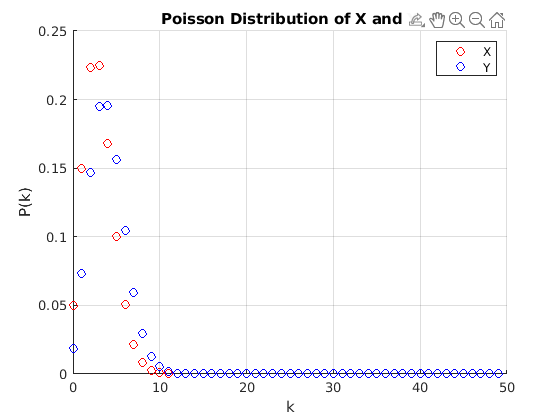

hold on;
t = 0:1:49;
scatter(t, Xfreq./n, 'r');
scatter(t, Yfreq./n, 'b');
hold off;

legend("X", "Y")
xlabel("k")
ylabel("P(k)")
title("Poisson Distribution of X and Y")
grid on

Calculating probability of Z

Zprob = zeros(1,26);

for i = 1:1:13
    for j = 1:1:13
        Zprob(1, i+j-1) = Zprob(1, i+j-1) + (Xfreq(1, i)/n)*(Yfreq(1, j)/n);
    end
end

Zprob

Zprob =     0.0009    0.0064    0.0223    0.0521    0.0912    0.1278    0.1490    0.1490    0.1304    0.1014    0.0710    0.0451    0.0263    0.0142    0.0071    0.0033    0.0014    0.0005    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0


Theoretically,


$$P(Z=k)=e^{-(\lambda_{X}+\lambda_{Y})}\frac{(\lambda_{x}+{\lambda_{Y}})^{k}}{k!}$$


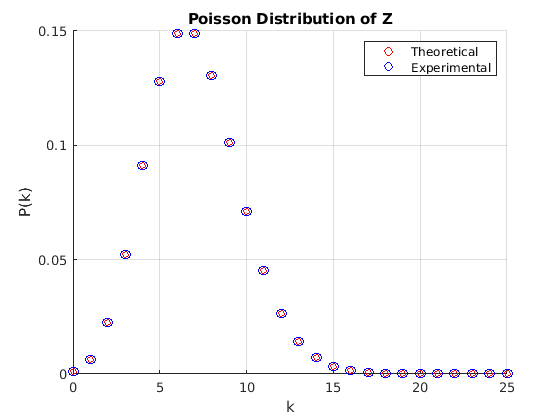

lambdaZ=7;

figure;
hold on;
for i=0:1:25
    scatter(i, pois(lambdaZ, i), 20, 'r');
    scatter(i, Zprob(i+1), 50, 'b');
end
hold off;

grid on
legend("Theoretical", "Experimental")
title("Poisson Distribution of Z")
xlabel("k")
ylabel("P(k)")

Function returns , $e^{-\lambda}\frac{\lambda^{k}}{k!}$

function ret = pois(lambda, k)
    ret = exp(-lambda)*power(lambda, k)/factorial(k);
end